# EEG Artefact Removal Pipeline

By Jason Ki

Pipeline for optimal denoising of EEG.

- Drift and line noise removal

- Sparse Noise Removal

- Correct Jitters by subtacting Mean

- Eye movement artifact removal

-  Reject outlier across samples and channels 

## Load all dependencies for preprocessing.

run ../load_all_deps; 

## Load eeg and metadata from SuperTuxKart experiment 

Get metadata.

rootDir = '..\'; 
metadataTablePath  = [rootDir 'data/metadata/metadataTable.mat'];
load(metadataTablePath);
[nRaces, nVariables] = size(metadataTable);

Here, we select race id 5 and 16 as example.

raceID1 = 5;
matFileDir = metadataTable.matFileDir{raceID1};
fileNamePrefix = 'epoched_eeg_';
matFileName1 = metadataTable.matFileName{raceID1};
matFilePath1 = [rootDir matFileDir fileNamePrefix matFileName1];

raceID2 = 16;
matFileDir = metadataTable.matFileDir{raceID2};
fileNamePrefix = 'epoched_eeg_';
matFileName2 = metadataTable.matFileName{raceID2};
matFilePath2 = [rootDir matFileDir fileNamePrefix matFileName2];

Load in the EEG

eegMatStr = 'eegEpochedDownsampled';
load(matFilePath1, eegMatStr, 'fsEegNew');
eval(['eeg1 = ' eegMatStr ';']);

load(matFilePath2, eegMatStr, 'fsEegNew');
eval(['eeg2 = ' eegMatStr ';']);

## Visualize the raw eeg data

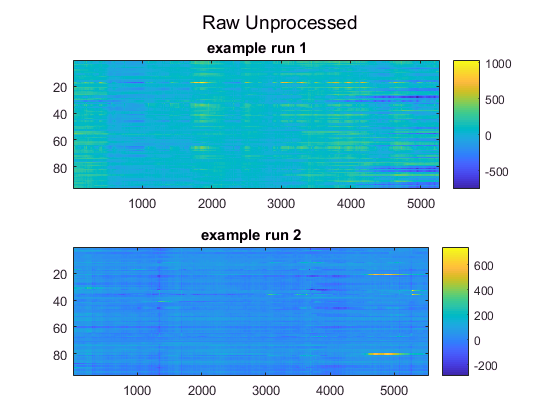

figure(1);
subplot(2,1,1);imagesc(eeg1');colorbar;title('example run 1')
subplot(2,1,2);imagesc(eeg2');colorbar;title('example run 2')
suptitle('Raw Unprocessed')

## 1) Drift and Line Noise Removal

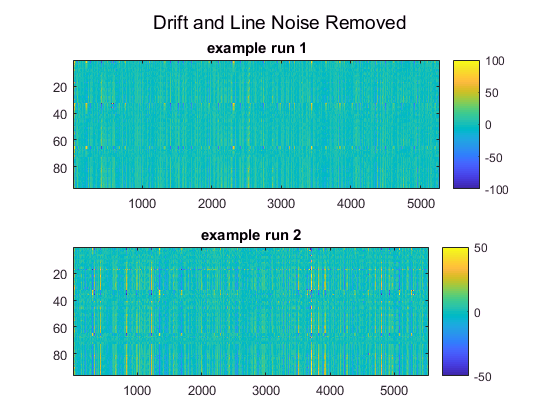

% High pass and 60hz bandstop line noise 
eegFiltered1 = filterEeg(eeg1,fs);
eegFiltered2 = filterEeg(eeg2,fs);

figure(2);
subplot(2,1,1);imagesc(eegFiltered1');colorbar;caxis([-100 100]);title('example run 1')
subplot(2,1,2);imagesc(eegFiltered2');colorbar;caxis([-50 50]);title('example run 2')
suptitle('Drift and Line Noise Removed')

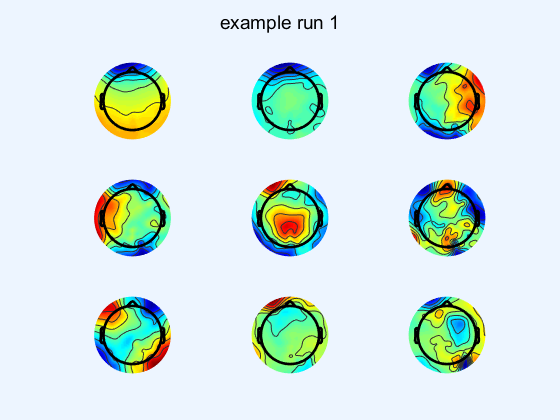

figure
[U, S, V] = drawSVDTopoplot(eegFiltered1, 'JBhead96_sym.loc'); suptitle('example run 1');

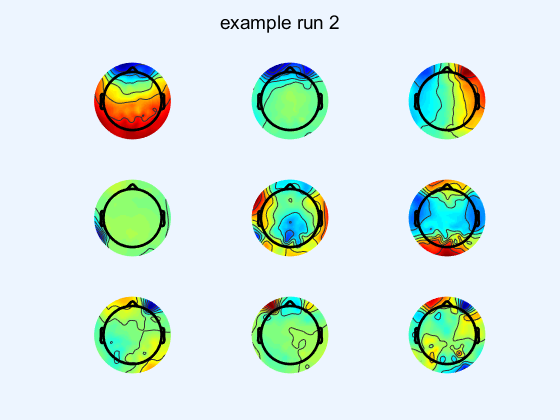

figure
[U, S, V] = drawSVDTopoplot(eegFiltered2, 'JBhead96_sym.loc'); suptitle('example run 2');

## 2) Sparse Data Removal using RPCA

eegRPCA1 = inexact_alm_rpca(eegFiltered1);

mu = 2.4668e-04

mu_bar = 2.4668e+03

rho = 1.5000

#svd 10 r(A) 28 |E|_0 329704 stopCriterion 0.017898
#svd 20 r(A) 53 |E|_0 459145 stopCriterion 7.2351e-05
#svd 30 r(A) 53 |E|_0 458014 stopCriterion 7.2449e-07


eegRPCA2 = inexact_alm_rpca(eegFiltered2);

mu = 3.0613e-04

mu_bar = 3.0613e+03

rho = 1.5000

#svd 10 r(A) 34 |E|_0 302779 stopCriterion 0.019196
#svd 20 r(A) 50 |E|_0 459879 stopCriterion 8.69e-05
#svd 30 r(A) 50 |E|_0 459750 stopCriterion 9.6995e-07


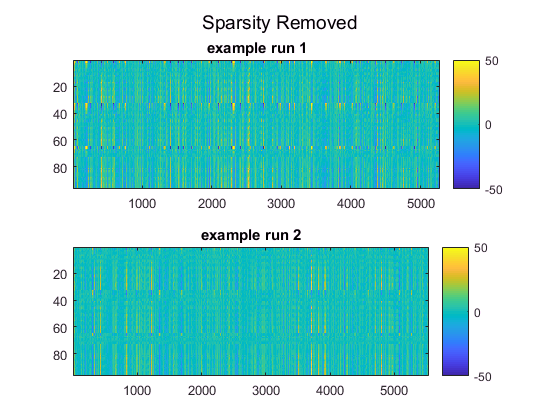


figure
subplot(2,1,1);imagesc(eegRPCA1');colorbar;caxis([-50 50]);title('example run 1')
subplot(2,1,2);imagesc(eegRPCA2');colorbar;caxis([-50 50]);title('example run 2')
suptitle('Sparsity Removed')

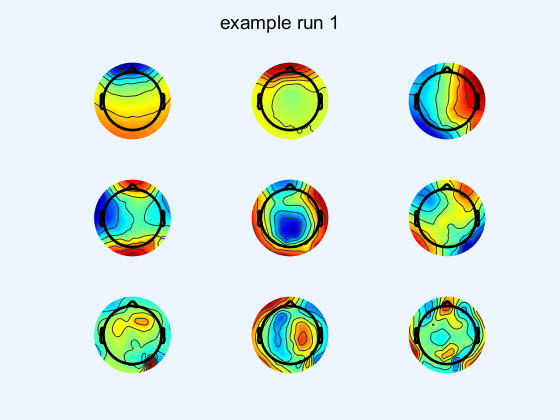

figure
[U, S, V] = drawSVDTopoplot(eegRPCA1, 'JBhead96_sym.loc'); suptitle('example run 1');

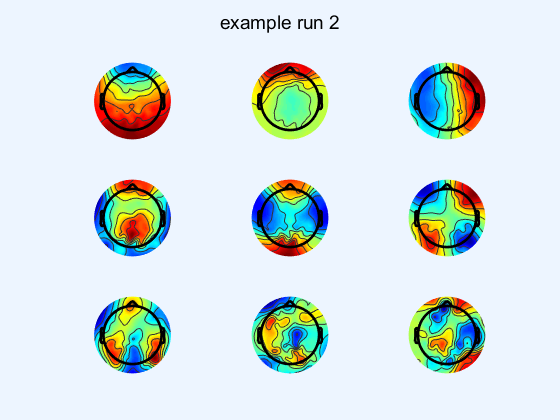

figure
[U, S, V] = drawSVDTopoplot(eegRPCA2, 'JBhead96_sym.loc'); suptitle('example run 2');

## 3) Correct Rapid Jitter Corruption 

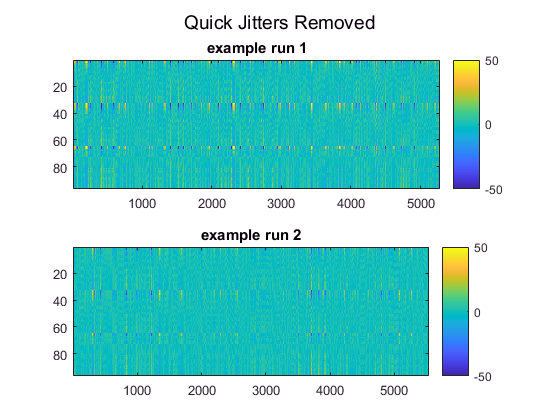

nChannels = 96;
eegOffset1 = eegRPCA1 - repmat(mean(eegRPCA1,2),1,nChannels);
eegOffset2 = eegRPCA2 - repmat(mean(eegRPCA2,2),1,nChannels);

figure
subplot(2,1,1);imagesc(eegOffset1');colorbar;caxis([-50 50]);title('example run 1')
subplot(2,1,2);imagesc(eegOffset2');colorbar;caxis([-50 50]);title('example run 2')
suptitle('Quick Jitters Removed')

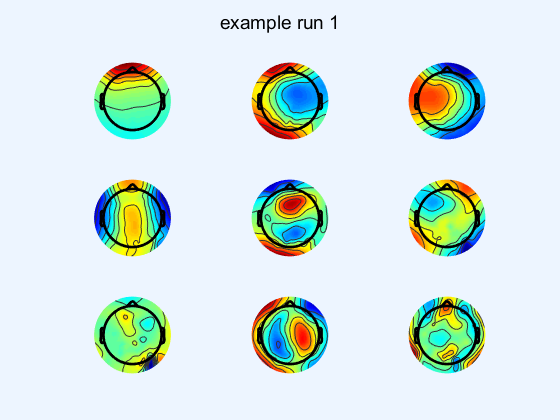

figure
[U, S, V] = drawSVDTopoplot(eegOffset1, 'JBhead96_sym.loc'); suptitle('example run 1');

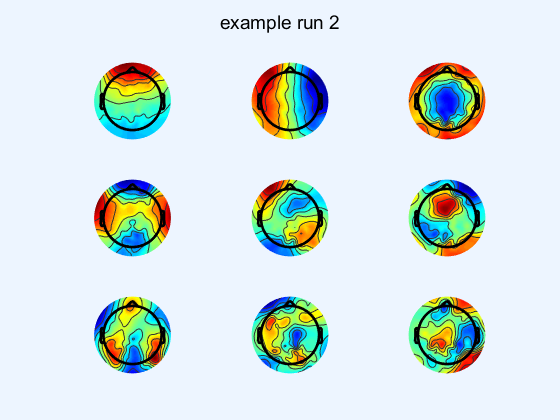

figure
[U, S, V] = drawSVDTopoplot(eegOffset2, 'JBhead96_sym.loc'); suptitle('example run 2');

## 4) Remove Eye Movement Artefact

Create virtual EOG since we do not have the original EOG.

virtualeog=zeros(96,4);
virtualeog([1 34],1)=1;
virtualeog([2 35],2)=1;
virtualeog(1,3)=1;
virtualeog(2,3)=-1;
virtualeog(33,4)=1;
virtualeog(36,4)=-1;

eogVirtual1 = eegOffset1*virtualeog;
eogVirtual2 = eegOffset2*virtualeog;

Subtract EOG via regression

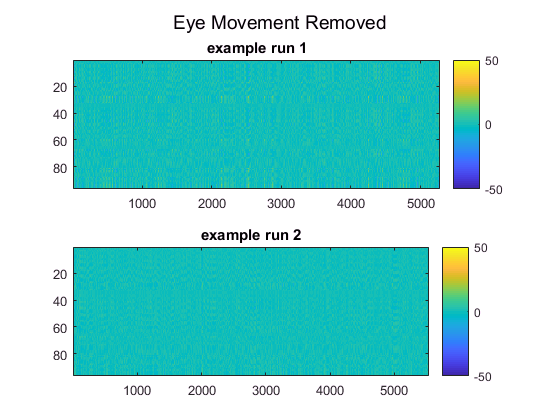

eegEyemovementRegressed1 = regressOut(eegOffset1',eogVirtual1')';
eegEyemovementRegressed2 = regressOut(eegOffset2',eogVirtual2')';

figure
subplot(2,1,1);imagesc(eegEyemovementRegressed1');colorbar;caxis([-50 50]);title('example run 1')
subplot(2,1,2);imagesc(eegEyemovementRegressed2');colorbar;caxis([-50 50]);title('example run 2')
suptitle('Eye Movement Removed')

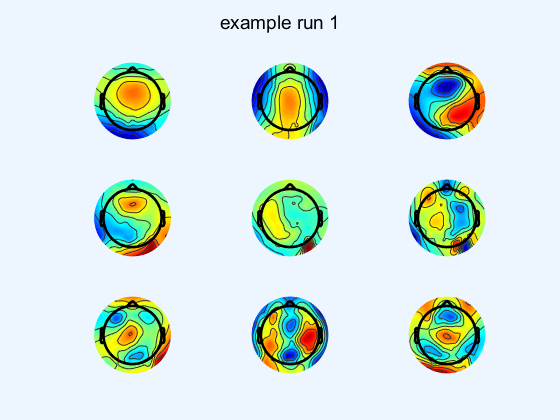

figure
[U, S, V] = drawSVDTopoplot(eegEyemovementRegressed1, 'JBhead96_sym.loc'); suptitle('example run 1');

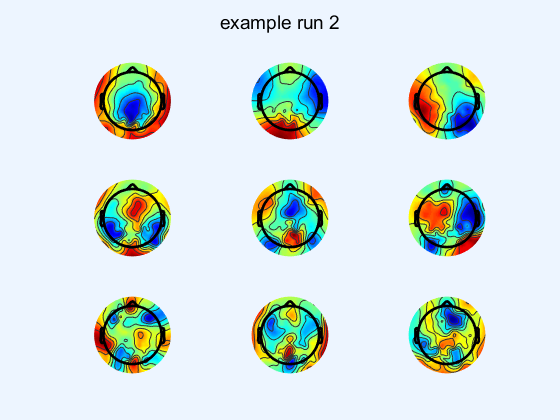

figure
[U, S, V] = drawSVDTopoplot(eegEyemovementRegressed2, 'JBhead96_sym.loc'); suptitle('example run 2');

## 5) Artefact Removal using Simple Statistic

Here, we remove corrupt samples across time and channel. We replace the artefact channels with Nan.

a) Remove samples based on standard deviation of samples across time.

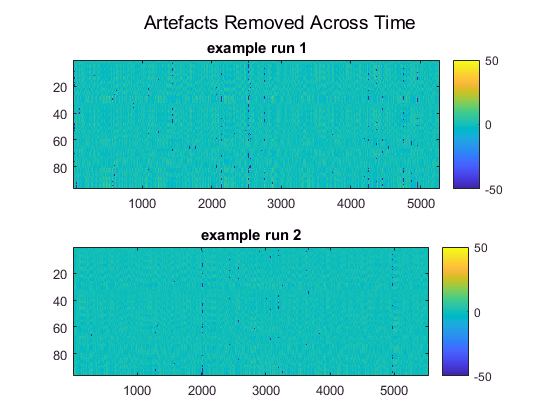

[eegBadSamplesRemoved1, mask1] = removeTimeSeriesArtifact(eegEyemovementRegressed1, 3, 1.5 , fs);    
[eegBadSamplesRemoved2, mask2] = removeTimeSeriesArtifact(eegEyemovementRegressed2, 3, 1.5 , fs);    

figure
subplot(2,1,1);imagesc(eegBadSamplesRemoved1');colorbar;caxis([-50 50]);title('example run 1')
subplot(2,1,2);imagesc(eegBadSamplesRemoved2');colorbar;caxis([-50 50]);title('example run 2')
suptitle('Artefacts Removed Across Time');

b) Remove samples based on standard deviation of samples across the channels.

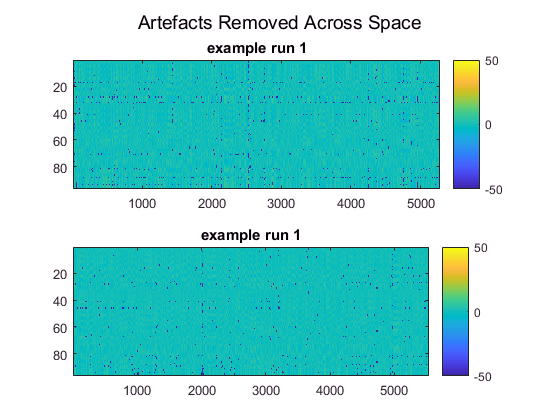

[eegBadSamplesRemoved1, mask1] = removeSpatialArtifact(eegBadSamplesRemoved1, 2.5);
[eegBadSamplesRemoved2, mask2] = removeSpatialArtifact(eegBadSamplesRemoved2, 2.5);

figure
subplot(2,1,1);imagesc(eegBadSamplesRemoved1');colorbar;caxis([-50 50]);title('example run 1')
subplot(2,1,2);imagesc(eegBadSamplesRemoved2');colorbar;caxis([-50 50]);title('example run 2')
suptitle('Artefacts Removed Across Space');

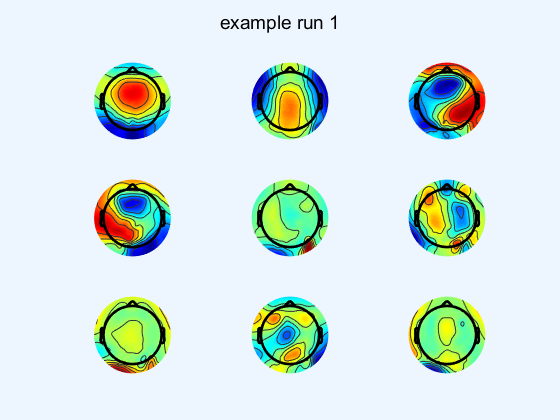


eegBadSamplesRemoved1_ = eegBadSamplesRemoved1;
eegBadSamplesRemoved2_ = eegBadSamplesRemoved2;
eegBadSamplesRemoved1_(isnan(eegBadSamplesRemoved1)) = 0;
eegBadSamplesRemoved2_(isnan(eegBadSamplesRemoved2)) = 0;

figure
[U, S, V] = drawSVDTopoplot(eegBadSamplesRemoved1_, 'JBhead96_sym.loc'); suptitle('example run 1');

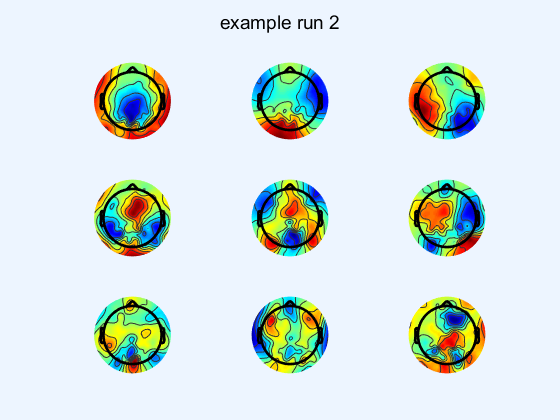

figure
[U, S, V] = drawSVDTopoplot(eegBadSamplesRemoved2_, 'JBhead96_sym.loc'); suptitle('example run 2');